假设对于微分方程ut=alpha*uxx;

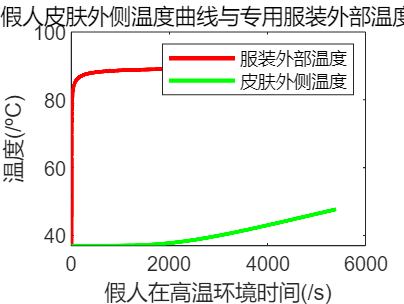

format long
% % end_t=[];%皮肤表面的温度
% c=[];%比热容
% rho=[];%密度
% d=[];%物体厚度
% lamda=[];%热传导率
% all_alpha=lamda./(c.*rho.*d);
dt=1;
dx=0.1256;
t=90*60;
L=0.6+6+3.6+5;
all_t=0:dt:t;
all_x=0:dx:L;
m=size(all_t,2);
n=size(all_x,2);
n1=(0.6/(10*dx))+1;
n2=((0.6+6)/dx)+1;
n3=((0.6+6+3.6)/dx)+1;
u=zeros(m,n+1);
u(:,1)=90;
u(:,end)=end_t;
u(1,2:end-1)=37;
for i=1:m-1
    for j=2:n-1
        if j<=n1
            u(i+1,j)=(u(i,j+1)+u(i,j-1))/2+(abs(u(i,j-1)-u(i+1,j-1)))*(((0.001*dx)^2)/(2*all_alpha(1,1)*dt));
        elseif j<=n2
            u(i+1,j)=(u(i,j+1)+u(i,j-1))/2+(abs(u(i,j-1)-u(i+1,j-1)))*(((0.001*dx)^2)/(2*all_alpha(2,1)*dt));
        elseif j<=n3
            u(i+1,j)=(u(i,j+1)+u(i,j-1))/2+(abs(u(i,j-1)-u(i+1,j-1)))*(((0.001*dx)^2)/(2*all_alpha(3,1)*dt));
        else
            u(i+1,j)=(u(i,j+1)+u(i,j-1))/2+(abs(u(i,j-1)-u(i+1,j-1)))*(((0.001*dx)^2)/(2*all_alpha(4,1)*dt));
        u(i+1,end-1)=u(i+1,end-2);
        end
    end
end
figure(1)
plot(1:m,u(:,2),'r-','LineWidth',2);
hold on
plot(1:m,u(:,end-1),'g-','LineWidth',2)
title('某时刻下假人皮肤外侧温度曲线与专用服装外部温度曲线对比图');
xlabel('假人在高温环境时间(/s)');
ylabel('温度(/ºC)');
legend('服装外部温度','皮肤外侧温度')
hold off

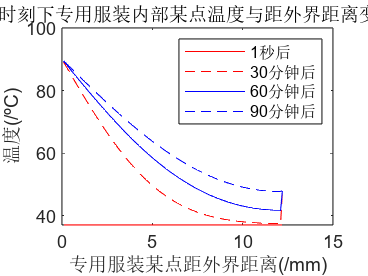

figure(2)
plot(0.1:0.1:n/10,u(1,2:end),'r-');
hold on
plot(0.1:0.1:n/10,u(1801,2:end),'r--');
hold on
plot(0.1:0.1:n/10,u(3601,2:end),'b-');
hold on
plot(0.1:0.1:n/10,u(5401,2:end),'b--');
title('某时刻下专用服装内部某点温度与距外界距离变化图');
xlabel('专用服装某点距外界距离(/mm)');
ylabel('温度(/ºC)');
legend('1秒后','30分钟后','60分钟后','90分钟后')

error_n1=0;
error_n5=0;
all_error=ones(1,m);
for j=1:m
    all_error(1,j)=abs(u(j,end-1)-u(j,end))/u(j,end);
end
for jj=1:m
    if all_error(1,jj)>0.1
        error_n1=error_n1+1;
        error_n5=error_n5+1;
    elseif all_error(1,jj)>0.05
        error_n5=error_n5+1;
    end
end
max_error=max(all_error);
min_error=min(all_error);
error=sum(all_error(1,1:1000))/(1000);
error1=error_n1/m;
error5=error_n5/m;
% nn=(n-1)/152;
% end_u=zeros(m,153);
% end_u(:,1)=u(:,1);
% for i=1:152
%     end_u(:,i+1)=u(:,152*nn+1);
% end
% end_u=ones(m,1);
% end_u(:,1)=u(:,end-1)-u(:,end);